gameState.players.pos

gameState.players(2:7).pos

for i = 2:size(gameState.players.pos, 1)-1
    gameState.players.pos(i, 1) = rand() * fieldWidth;
    gameState.players.pos(i, 2) = rand() * fieldLength;
end


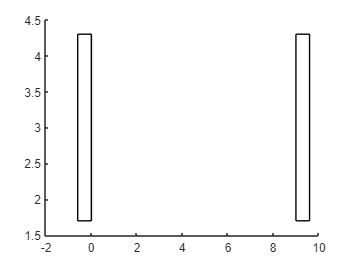

 rectangle('Position', [-0.6 1.7 0.6 2.6],'LineWidth', 0.125);
 hold on;
    rectangle('Position', [9 1.7 0.6 2.6],'LineWidth', 0.125);
 hold off;

% Define the dimensions of the soccer field
fieldWidth = 100; % in meters
fieldLength = 70; % in meters

% Define the number of players on each team
numPlayers = 8;

% Generate random x,y coordinates for each player
team1 = rand(numPlayers, 2) .* [fieldWidth, fieldLength];
team2 = rand(numPlayers, 2) .* [fieldWidth, fieldLength];

% Plot the players on the field
figure
hold on
plot(team1(:,1), team1(:,2), 'ro')
plot(team2(:,1), team2(:,2), 'bx')
axis([0 fieldWidth 0 fieldLength])
title('Randomized Soccer Player Positions')
xlabel('Field Width (m)')
ylabel('Field Length (m)')
legend('Team 1', 'Team 2')

fieldLimitsX(2)

% Define the field boundaries
fieldWidth = fieldLimitsX(2);    % meters
fieldLength = fieldLimitsY(2);  % meters

% Define the range of valid positions
minX = 2;
maxX = fieldLimitsY(2) - 5;
minY = 0.5;
maxY = fieldLimitsX(2) - 0.5;

% Load the game state


% Create an array of all possible positions between the penalty boxes
allPositions = zeros(90,120, 2)

allPositions = allPositions(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

for i = 1:90
    for j = 1:120
        allPositions(i,j,:) = [i*0.060, j*0.08];
    end
end
allPositions = reshape(allPositions, [], 2)

allPositions =     0.0600    0.0800
    0.1200    0.0800
    0.1800    0.0800
    0.2400    0.0800
    0.3000    0.0800
    0.3600    0.0800
    0.4200    0.0800
    0.4800    0.0800
    0.5400    0.0800
    0.6000    0.0800


allPositions((allPositions(:,1) < 2.5 ),:) = []

allPositions =     2.5200    0.0800
    2.5800    0.0800
    2.6400    0.0800
    2.7000    0.0800
    2.7600    0.0800
    2.8200    0.0800
    2.8800    0.0800
    2.9400    0.0800
    3.0000    0.0800
    3.0600    0.0800


allPositions((allPositions(:,1) > 6.8 ),:) = []

allPositions =     2.5200    0.0800
    2.5800    0.0800
    2.6400    0.0800
    2.7000    0.0800
    2.7600    0.0800
    2.8200    0.0800
    2.8800    0.0800
    2.9400    0.0800
    3.0000    0.0800
    3.0600    0.0800


allPositions((allPositions(:,2) > 5.8 ),:) = []

allPositions =     2.5200    0.0800
    2.5800    0.0800
    2.6400    0.0800
    2.7000    0.0800
    2.7600    0.0800
    2.8200    0.0800
    2.8800    0.0800
    2.9400    0.0800
    3.0000    0.0800
    3.0600    0.0800


allPositions((allPositions(:,2) < 0.08 ),:) = []

allPositions =     2.5200    0.0800
    2.5800    0.0800
    2.6400    0.0800
    2.7000    0.0800
    2.7600    0.0800
    2.8200    0.0800
    2.8800    0.0800
    2.9400    0.0800
    3.0000    0.0800
    3.0600    0.0800


% Shuffle the array of0 possible positions
shuffledPositions = allPositions(randperm(size(allPositions,1)), :)

shuffledPositions =     3.8400    1.9200
    4.0800    5.6800
    3.1200    2.7200
    3.3000    0.2400
    3.6600    0.0800
    2.5800    0.8000
    4.1400    0.9600
    4.9800    4.8800
    4.5600    2.4000
    2.5800    0.4800


shuffledPositions = shuffledPositions(randperm(size(shuffledPositions,1)), :)

shuffledPositions =     4.0800    0.5600
    3.3600    2.8000
    4.0200    0.8000
    3.8400    3.2000
    3.3000    0.3200
    5.2800    1.2000
    5.0400    4.8000
    2.8200    2.8000
    4.2000    5.6800
    2.9400    1.7600



% Assign the shuffled positions to the players
for i = 1:length(gameState.players)
    if i ~= 1 && i ~= 8
        gameState.players(i).pos = shuffledPositions(i,:)
    end
end

gameState = struct with fields:
      state: KickOff
    players: [1×8 struct]
       ball: [1×1 struct]
      score: [1×1 struct]
       time: 1


gameState = struct with fields:
      state: KickOff
    players: [1×8 struct]
       ball: [1×1 struct]
      score: [1×1 struct]
       time: 1


gameState = struct with fields:
      state: KickOff
    players: [1×8 struct]
       ball: [1×1 struct]
      score: [1×1 struct]
       time: 1


gameState = struct with fields:
      state: KickOff
    players: [1×8 struct]
       ball: [1×1 struct]
      score: [1×1 struct]
       time: 1


 gameState.ball.position = [7.5 3];
 gameState.players(1).pos = [0.5,3];
 gameState.players(8).pos = [8 3];

max(shuffledPositions(:,2))

ans = 6.4800

allPositions = zeros(90,120, 2)

allPositions = allPositions(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

for i = 1:90
    for j = 1:120
        allPositions(i,j,:) = [i*0.045, j*0.03];
    end
end

allPositions = reshape(allPositions, [], 2)

allPositions =     0.0450    0.0300
    0.0900    0.0300
    0.1350    0.0300
    0.1800    0.0300
    0.2250    0.0300
    0.2700    0.0300
    0.3150    0.0300
    0.3600    0.0300
    0.4050    0.0300
    0.4500    0.0300


shuffledPositions = allPositions(randperm(size(allPositions,1)), :)

shuffledPositions =     0.9000    3.1200
    0.4050    0.8700
    3.5100    2.5800
    2.0700    2.4600
    2.2050    0.7800
    2.6100    1.2000
    2.7000    3.2100
    0.2700    3.3600
    2.4750    1.8600
    2.5650    1.4700


class(shuffledPositions)

ans = 'double'

shuffledPositions(1, ...
    :)

ans =     0.9000    3.1200


shuffledPositions((shuffledPositions(:,1) > 2 & shuffledPositions(:,2) < 7 ),:)

ans =     3.5100    2.5800
    2.0700    2.4600
    2.2050    0.7800
    2.6100    1.2000
    2.7000    3.2100
    2.4750    1.8600
    2.5650    1.4700
    3.8250    1.6500
    3.9600    2.5800
    3.4650    2.1000


%shuffledPositions(:,1) > 2 & shuffledPositions(:,2) < 7 

N = 10;
A = randi(9, N, 6);                         % Create Data
B = randi(9, N, 1);                         % Create Data
Q = A                                     % Copy For Reference

Q =      3     3     3     6     8     9
     5     4     4     3     4     1
     6     3     7     9     7     9
     3     6     6     4     8     5
     3     1     3     1     5     5
     3     8     8     7     8     1
     2     2     9     8     9     9
     2     2     5     2     9     9
     7     9     8     6     7     5
     1     8     2     1     3     9


B

B =      5
     3
     9
     4
     8
     8
     3
     5
     6
     5


A(A(:,6) > B,:) = []

A =      5     4     4     3     4     1
     6     3     7     9     7     9
     3     1     3     1     5     5
     3     8     8     7     8     1
     7     9     8     6     7     5


A(:,2)

ans =      4
     3
     1
     8
     9


scatter(gameState.players.pos(1,1),gameState.players.pos(1,2))

Intermediate dot '.' indexing produced a comma-separated list with 8 values, but it must produce a single value when followed by
subsequent indexing operations.

Related documentation

gameState.players(1:8).pos

atest(1,1)

allPositions


    %PLOTPLAYERS Summary of this function goes here
    %   Detailed explanation goes here
    r = 0.31;
    color = ['r','b'];
    hold on
    for idx = 1:8
        [gameState.players(idx).pos(1)-r, gameState.players(idx).pos(2)-r]
        rectangle('Position',[gameState.players(idx).pos(1)-r, gameState.players(idx).pos(2)-r, 2*r, 2*r],'Curvature', [1,1], 'FaceColor',color(gameState.players(idx).team+1))
    end
    hold off

% Define the field dimensions
fieldWidth = 9;
fieldHeight = 6;

% Define the position ranges for each player
team0PosRanges = {[2 0], [7 6]};
team1PosRanges = {[2 0], [3 5.5], [7 6]};

% Create a list of available positions on the field
availablePositions = ones(fieldHeight+1, fieldWidth+1);
availablePositions(1,:) = 0;
availablePositions(:,1) = 0;
availablePositions(fieldHeight+1,:) = 0;
availablePositions(:,fieldWidth+1) = 0;

% Place player 2 in team 1 close to its home penalty box
pos2 = [randi([2 3]), randi([1 5])];
availablePositions(pos2(2)+1, pos2(1)+1) = 0;

% Randomly assign positions to the remaining players in team 0
team0Players = [1 3 4];
for i = 1:numel(team0Players)
    player = team0Players(i);
    pos = [];
    while isempty(pos)
        x = randi([team0PosRanges{1}(1), team0PosRanges{2}(1)]);
        y = randi([team0PosRanges{1}(2), team0PosRanges{2}(2)]);
        if availablePositions(y+1, x+1) == 1
            pos = [x y];
            availablePositions(y+1, x+1) = 0;
        end
    end
    gameState.players(player).pos = pos;
end

% Randomly assign positions to the remaining players in team 1
team1Players = [5 6 7];
for i = 1:numel(team1Players)
    player = team1Players(i);
    pos = [];
    while isempty(pos)
        x = randi([team1PosRanges{1}(1), team1PosRanges{2}(1)]);
        y = randi([team1PosRanges{1}(2), team1PosRanges{2}(2)]);
        if availablePositions(y+1, x+1) == 1
            pos = [x y];
            availablePositions(y+1, x+1) = 0;
        end
    end
    gameState.players(player).pos = pos;
end